**FILTRADO IIR SEÑAL DE LTSPICE**

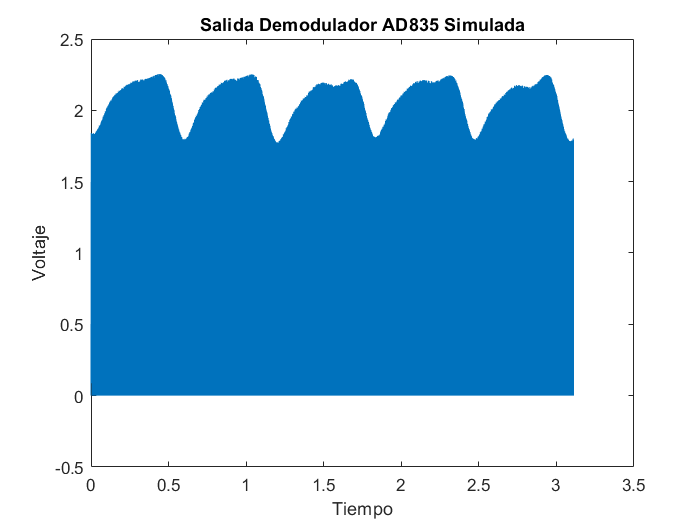

% Ruta del archivo
ruta_signal = 'D:\Master\Segundo Cuatrimestre\Trabajo Fin de Master\TFM presion arterial\Matlab\demod1.txt';

% Guardamos los datos
datos_signal = dlmread(ruta_signal, '\t', 1, 0);

% Extraemos las columnas
base_tiempos = datos_signal(:, 1);
voltaje = datos_signal(:, 2);

% Representamos los datos guardados
plot(base_tiempos, voltaje);
xlabel('Tiempo');
ylabel('Voltaje');
title('Salida Demodulador AD835 Simulada');

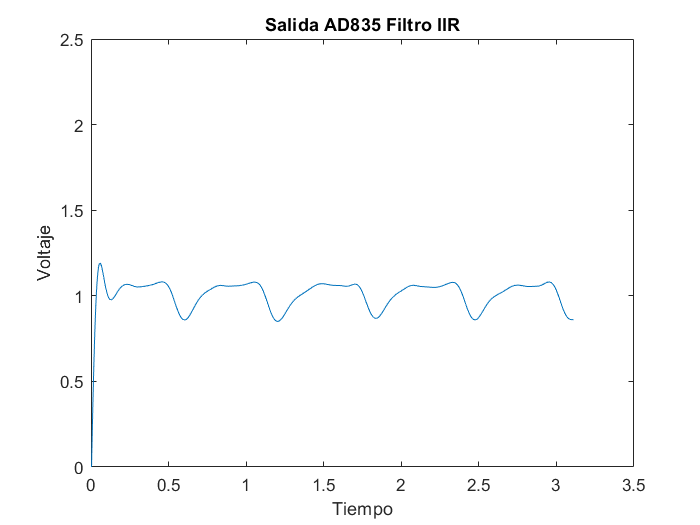


% Procedemos al filtrado de la señal con un IIR
fs = 1 / mean(diff(base_tiempos));
f_corte = 7;
orden_filtro = 2;
filtro = designfilt('lowpassiir', 'FilterOrder', orden_filtro, 'PassbandFrequency', f_corte, 'SampleRate', fs);
voltaje_filtrado = filtfilt(filtro, voltaje);

% Representamos la señal filtrada
plot(base_tiempos, voltaje_filtrado);
xlabel('Tiempo');
ylabel('Voltaje');
xlim([0 3.5]);
ylim([0 2.5]);
title('Salida AD835 Filtro IIR');

**FILTRADO FIR SEÑAL DE LTSPICE**

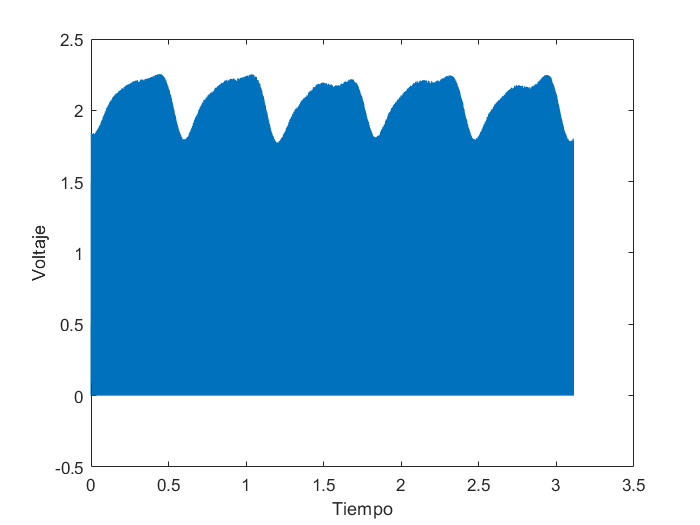

% Ruta del archivo
ruta_signal = 'D:\Master\Segundo Cuatrimestre\Trabajo Fin de Master\TFM presion arterial\Matlab\demod1.txt';

% Guardamos los datos
datos_signal = dlmread(ruta_signal, '\t', 1, 0);

% Extraemos las columnas
base_tiempos = datos_signal(:, 1);
voltaje = datos_signal(:, 2);

% Representamos los datos guardados
plot(base_tiempos, voltaje);
xlabel('Tiempo');
ylabel('Voltaje');

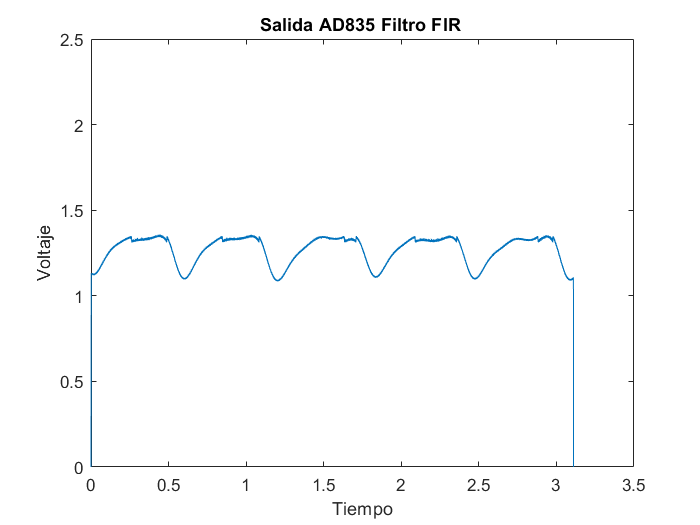


% Procedemos al filtrado de la señal con un FIR
fs = 1 / mean(diff(base_tiempos));
f_corte = 7;
orden_filtro =500;
filtro = designfilt('lowpassfir', 'FilterOrder', orden_filtro, 'CutoffFrequency', f_corte, 'SampleRate', fs);
voltaje_filtrado = filtfilt(filtro, voltaje);

% Representamos la señal filtrada
plot(base_tiempos, voltaje_filtrado);
xlabel('Tiempo');
ylabel('Voltaje');
xlim([0 3.5]);
ylim([0 2.5]);
title('Salida AD835 Filtro FIR ');